# PreprocessData

## Import Data

clear
clear all
close all
clc
format shorteng
data = import_whole('Set 1.txt');

## Clean Data

% Swap Uin and Q
v = data(:, 5);
data(:, 5) = data(:, 6);
data(:, 6) = v;
clear v
% convert Tamb from kelvin to DegC
data(:, "Tamb") = data(:, "Tamb") - 273.15;
% convert from m to mm
data(:, "length") = data(:, "length") .* 1000;
data(:, "hc") = data(:, "hc") .* 1000;
data(:, "wc") = data(:, "wc") .* 1000;

% assign Names
units = ["mm" "mm" "mm" "degC" "m s^{-1}" "W m^{-2}" "degC" "degC" "degC" "degC" "degC" "degC" "Pa" "Pa" "Pa" "m/s" "m/s" "degC" "degC"];
features = ["hc" "wc" "length" "Tamb" "Uin" "Q"];
f_units = ["mm" "mm" "mm" "degC" "m s^{-1}" "W m^{-2}"];
f_title = ["{\itH_{c}}" "{\itW_{c}}" "{\itL}" "{\itT_{amb}}" "{\itU_{in}}" "{\itQ}"];

targets = ["TemperaturedegCBoundaryProbe1" "TemperaturedegCBackAirTemperatureProbe2" "TemperaturedegCBackSolidTemperatureProbe3" "TemperaturedegCFrontAllTemperatureProbe4" "TemperaturedegCFrontAirTemperatureProbe5" "TemperaturedegCFrontSolidTemperatureProbe6" "PressurePaPressureProbe1" "PressurePaPressureProbe2" "PressurePaPressureProbe3" "VelocityMagnitudemsSpeedProbe1" "VelocityMagnitudemsSpeedProbe2" "TemperaturedegCStackTemperatureProbe1" "TemperaturedegCStackTemperatureProbe"];
t_units = ["degC" "degC" "degC" "degC" "degC" "degC" "Pa" "Pa" "Pa" "m/s" "m/s" "degC" "degC"];
t_title = ["Boundary Probe 1" "Back Air Temperature Probe 2" "Back Solid Temperature Probe 3" " Front All Temperature Probe 4" "Front Air Temperature Probe 5" "Front Solid Temperature Probe 6" "Pressure Probe 1" "Pressure Probe 2" "Pressure Probe 3" "Speed Probe 1" "Speed Probe 2" "Stack Temperature Probe 1" "Stack Temperature Probe"];
t_label = ["Temperature" "Temperature" "Temperature" "Temperature" "Temperature" "Temperature" "Pressure" "Pressure" "Pressure" "Velocity Magnitude" "Velocity Magnitude" "Temperature" "Temperature"];

% set colours
blue = [0.00 0.00 0.55];
red = [0.65 0.16 0.16];
green = [0.00 0.39 0.00];
pink = [1.00,0.00,1.00];

## Histogram of T with optimal temperature range

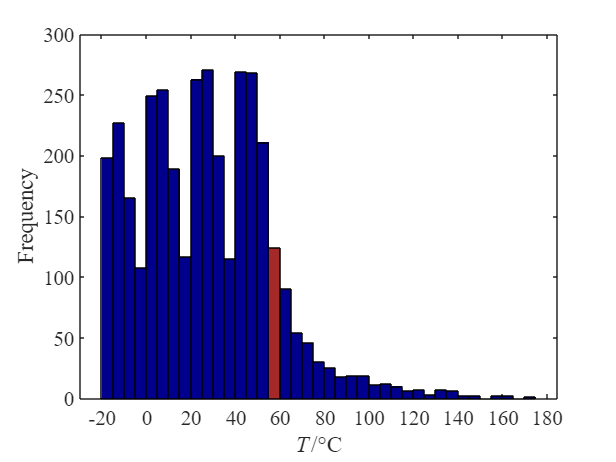

figure(1);
temp = data{:, 18};
mask = (55<temp) & (temp<60);

hold on
s = histogram(temp(~mask),'FaceColor',blue,'FaceAlpha', 1);
histogram(temp(mask),s.BinEdges,'FaceColor',red,'FaceAlpha', 1);
hold off
% title("Histogram of {\itT}")
% legend(["", "Optimal Temperature Range"])
xlabel("{\itT}/{{\circ}}C")
ylabel("Frequency")
v=get(1,'currentaxes');
set(v,'FontSize',14,'FontName','Times New Roman', 'XTick', -20:20:180);
box on

## Parallel Coordinate Plot (Temperature)

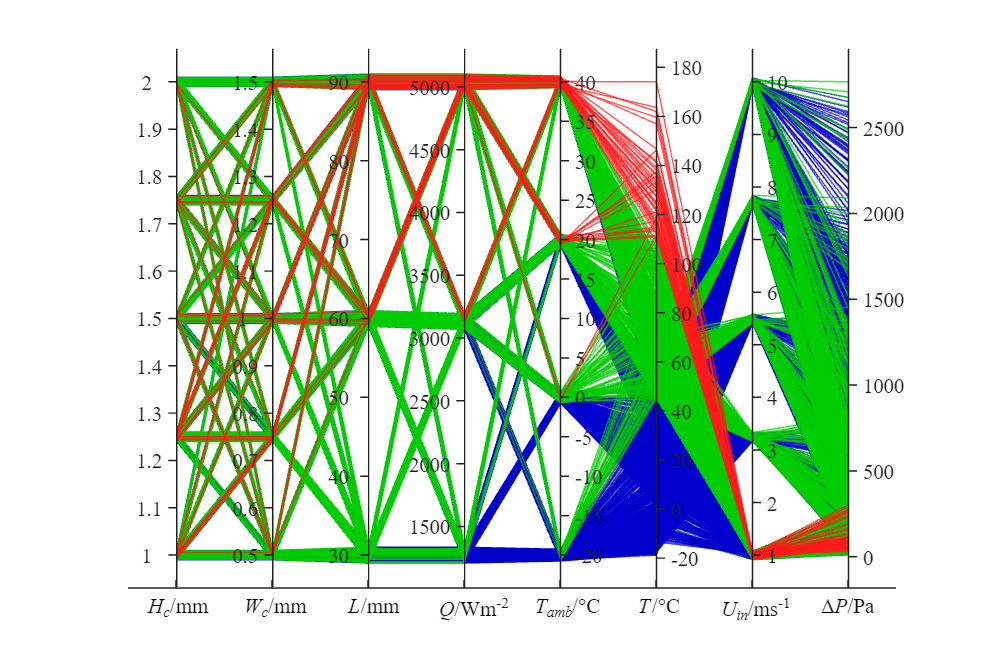

% set binEdges
par_data = data{:,[1:6 15 18]};
temp_vals = par_data(:, 8)';
binEdges = [min(temp_vals) 45 110 max(temp_vals)];
bins = {'Low', 'Medium', 'High'};
groupTemp = discretize(temp_vals,binEdges,'categorical',bins);
figure(2);
par_data = par_data(:, [1 2 3 5 4 8 6 7]);
p = parallelplot(par_data,'Color',[[0.00 0.00 0.80];[0.00 0.80 0.00];[1.00 0.10 0.10]], ...
                'GroupData',groupTemp, ...
                'LegendVisible',0,...
                'CoordinateTickLabels', {});
set(gcf, 'Position', [0 0 900 600]);
v=get(2,'CurrentAxes');
set(v,'FontSize',14,'FontName','Times New Roman');
annotation('textbox',[0.140 0.0422 0.0626 0.0633],'String','{\itH_{c}}/mm','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.237 0.0422 0.0626 0.0633],'String','{\itW_{c}}/mm','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.341 0.0422 0.0626 0.0633],'String','{\itL}/mm','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.434 0.0422 0.0626 0.0633],'String','{\itQ}/Wm^{-2}','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.531 0.0422 0.0626 0.0633],'String','{\itT_{amb}}/{{\circ}}C','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.635 0.0422 0.0626 0.0633],'String','{\itT}/{{\circ}}C','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.719 0.0422 0.0626 0.0633],'String','{\itU_{in}}/ms^{-1}','FontSize',14,'FontName','Times New Roman','FitBoxToText','off','EdgeColor','none');
annotation('textbox',[0.820 0.0422 0.0626 0.0633],'String','\Delta{\itP}/Pa','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');

## Parallel Coordinate Plot (Pressure)

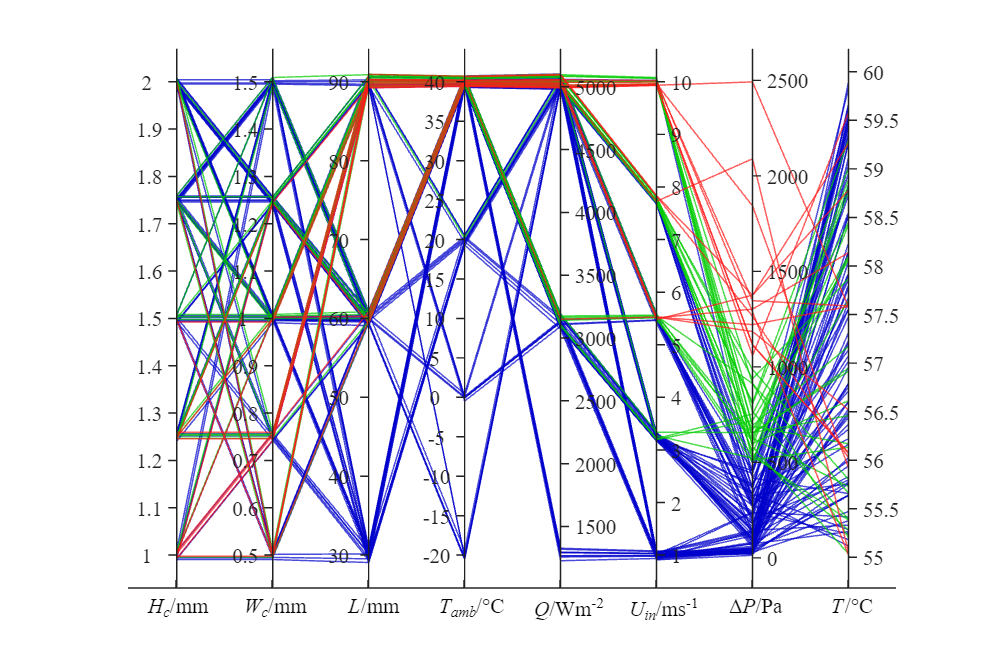

% obtain all rows that lie within optimal temperature range
par_data = data{:,[1:6 15 18]};
mask_data = par_data(mask, :);
pressure_vals = mask_data(:, 7)';
% set binEdges
binEdges = [min(pressure_vals) 500 1000 max(pressure_vals)];
bins = {'Low', 'Medium', 'High'};
groupPressure = discretize(pressure_vals,binEdges,'categorical',bins);

figure(3);
p = parallelplot(mask_data,'Color',[[0.00 0.00 0.80];[0.00 0.80 0.00];[1.00 0.10 0.10]], ...
            'GroupData',groupPressure, ...
            'LegendVisible',0, ...
            'CoordinateTickLabels', {});
set(gcf, 'Position', [0 0 900 600]);
v=get(3,'currentaxes');
set(v,'FontSize',14,'FontName','Times New Roman');
annotation('textbox',[0.140 0.0422 0.0626 0.0633],'String','{\itH_{c}}/mm','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.237 0.0422 0.0626 0.0633],'String','{\itW_{c}}/mm','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.341 0.0422 0.0626 0.0633],'String','{\itL}/mm','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.434 0.0422 0.0626 0.0633],'String','{\itT_{amb}}/{{\circ}}C','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.530 0.0422 0.0626 0.0633],'String','{\itQ}/Wm^{-2}','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.626 0.0422 0.0626 0.0633],'String','{\itU_{in}}/ms^{-1}','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');
annotation('textbox',[0.727 0.0422 0.0626 0.0633],'String','\Delta{\itP}/Pa','FontSize',14,'FontName','Times New Roman','FitBoxToText','off','EdgeColor','none');
annotation('textbox',[0.830 0.0422 0.0626 0.0633],'String','{\itT}/{{\circ}}C','FontSize',14,'FontName','Times New Roman','FitBoxToText','on','EdgeColor','none');

## Scatter by Targets

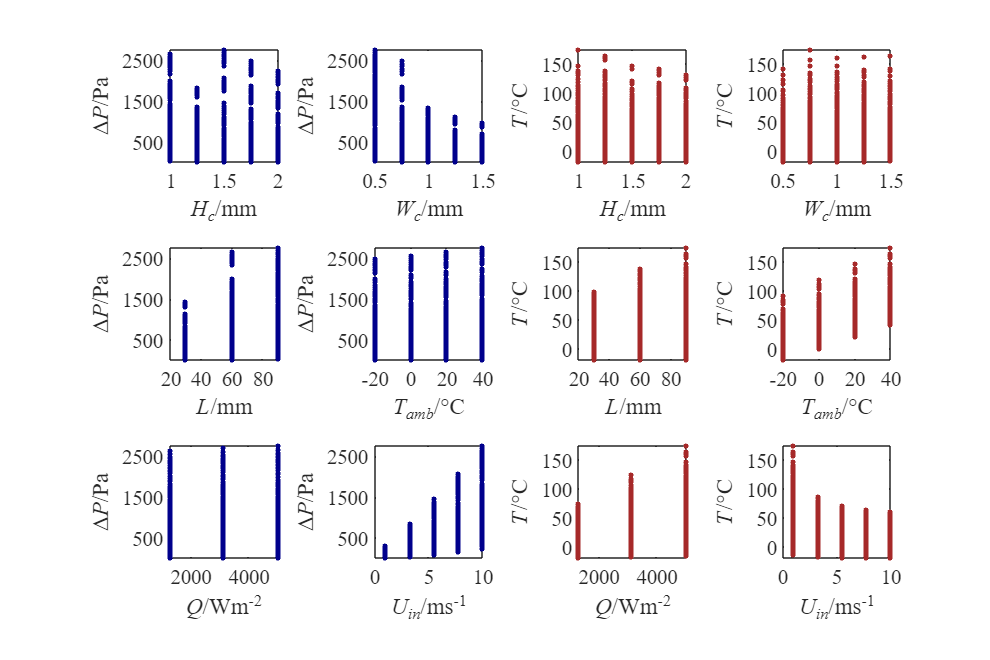

% configure data
s_data = data{:,[1:6 15 18]};
pressure_vals = s_data(:, 7)';
pressure_range = [min(pressure_vals) max(pressure_vals)];
temp_vals = s_data(:, 8)';
temp_range = [min(temp_vals) max(temp_vals)];
x_label = ["{\itH_{c}}/mm" "{\itW_{c}}/mm" "{\itL}/mm" "{\itT_{amb}}/{{\circ}}C" "{\itQ}/Wm^{-2}" "{\itU_{in}}/ms^{-1}"];
x_ticks = {[1 1.5 2], [0.5 1 1.5], [20 40 60 80], [-20 0 20 40], [2000 3000 4000 5000], [0 5 10]};

figure(4);
set(gcf, 'Position', [0 0 900 600]);
% plot pressure plots
j = 1;
for i = [1 2 5 6 9 10]
    subplot(3,4,i);
    plot(s_data(:, j),s_data(:, 7), 'o','MarkerEdgeColor',blue,'MarkerFaceColor',blue,'MarkerSize',3);
    ylim(pressure_range);
    yticks([500 1500 2500]);
    if j == 3
        xlim([19.999 max(s_data(:, j))]);
    elseif j == 4
        xlim([-20.001 max(s_data(:, j))]);
    end
    xtickangle = 0;
    xlabel(x_label(j));
    ylabel('\Delta{\itP}/Pa');
    v=get(4,'currentaxes');
    set(v,'FontSize',14,'FontName','Times New Roman');
    j = 1+j;
end
% plot temperature plots
j = 1;
for i = [3 4 7 8 11 12]
    subplot(3,4,i);
    plot(s_data(:, j),s_data(:, 8), 'o','MarkerEdgeColor',red,'MarkerFaceColor',red,'MarkerSize',3);
    ylim(temp_range);
    if j == 3
        xlim([19.999 max(s_data(:, j))]);
    elseif j == 4
        xlim([-20.001 max(s_data(:, j))]);
    end
    xlabel(x_label(j));
    ylabel('{\itT}/{{\circ}}C')
    v=get(4,'currentaxes');
    set(v,'FontSize',14,'FontName','Times New Roman');
    j = 1+j;
end

## Correlation Heatmap (main targets)

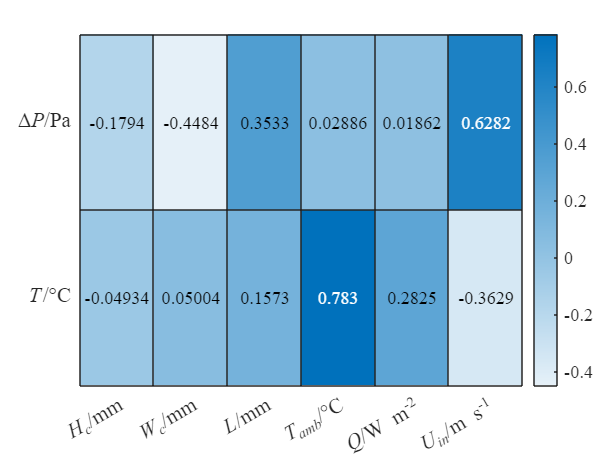

figure(5);
r = corr(data{:,:}, Type="Pearson");
r = r([15 18], 1:6);
h = heatmap(r,'MissingDataColor','w');
% title("Correlation Heatmap (Pearson)")
h.XDisplayLabels = ["{\itH_{c}}/mm" "{\itW_{c}}/mm" "{\itL}/mm" "{\itT_{amb}}/{{\circ}}C" "{\itQ}/W m^{-2}" "{\itU_{in}}/m s^{-1}"];
h.YDisplayLabels = ["\Delta{\itP}/Pa" "{\itT}/{{\circ}}C"];
set(h,'FontSize',14,'FontName','Times New Roman');

## Others

size(data)

ans =      3.6000e+003    19.0000e+000


summary(data)

Variables:

    hc: 3600×1 double

        Values:

            Min           1   
            Median      1.5   
            Max           2   

    wc: 3600×1 double

        Values:

            Min         0.5   
            Median        1   
            Max         1.5   

    length: 3600×1 double

        Values:

            Min          30   
            Median       60   
            Max          90   

    Tamb: 3600×1 double

        Values:

            Min         -20   
            Median       10   
            Max          40   

    Q: 3600×1 double

        Values:

            Min         1272  
            Median      3132  
            Max         5040  

    Uin: 3600×1 double

        Values:

            Min           1   
            Median      5.5   
            Max          10   

    TemperaturedegCBoundaryProbe1: 3600×1 double

        V

### Individual Feature

var = features(2);
groupsummary(data, var, ["mean" "std" "var"], ["PressurePaPressureProbe3" "TemperaturedegCStackTemperatureProbe"])

ans = 5×8 table
     wc     GroupCount    mean_PressurePaPressureProbe3    std_PressurePaPressureProbe3    var_PressurePaPressureProbe3    mean_TemperaturedegCStackTemperatureProbe    std_TemperaturedegCStackTemperatureProbe    var_TemperaturedegCStackTemperatureProbe
    ____    __________    _____________________________    ____________________________    ____________________________    _________________________________________    ________________________________________    ________________________________________

     0.5       600                    872.2                           669.24                        4.4788e+05                              23.774                                       28.485              

### One or More Features

% adjust range of features to select which features to include
grpsummary = groupsummary(data, features(4:5), ["mean", "std","var"], ["PressurePaPressureProbe3" "TemperaturedegCStackTemperatureProbe"])

grpsummary = 20×9 table
    Tamb    Uin     GroupCount    mean_PressurePaPressureProbe3    std_PressurePaPressureProbe3    var_PressurePaPressureProbe3    mean_TemperaturedegCStackTemperatureProbe    std_TemperaturedegCStackTemperatureProbe    var_TemperaturedegCStackTemperatureProbe
    ____    ____    __________    _____________________________    ____________________________    ____________________________    _________________________________________    ________________________________________    ________________________________________

    -20        1       180                   63.657                           53.904                            2905.6                             

## KDE Distribution Plots

### Individual Plot

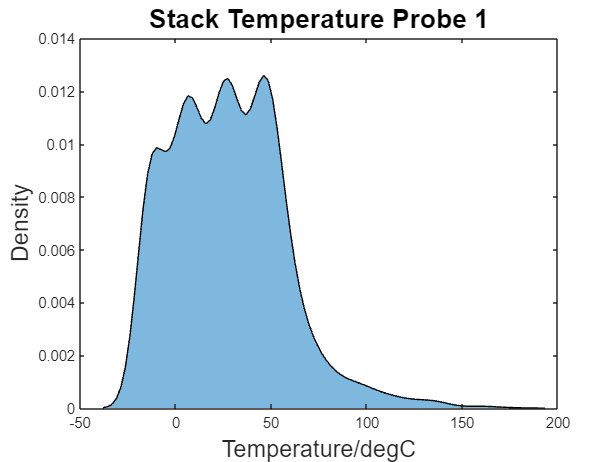

figure;
var = targets(12);
[f,xf] = kde(data{:,var});
ar = area(xf,f);
ar.FaceAlpha = 0.5;
index = targets==var;
title(t_title(index), "FontSize",18)
xlabel(t_label(index) + "/" + t_units(index), "FontSize",16)
ylabel('Density', "FontSize",16)

### All Plots

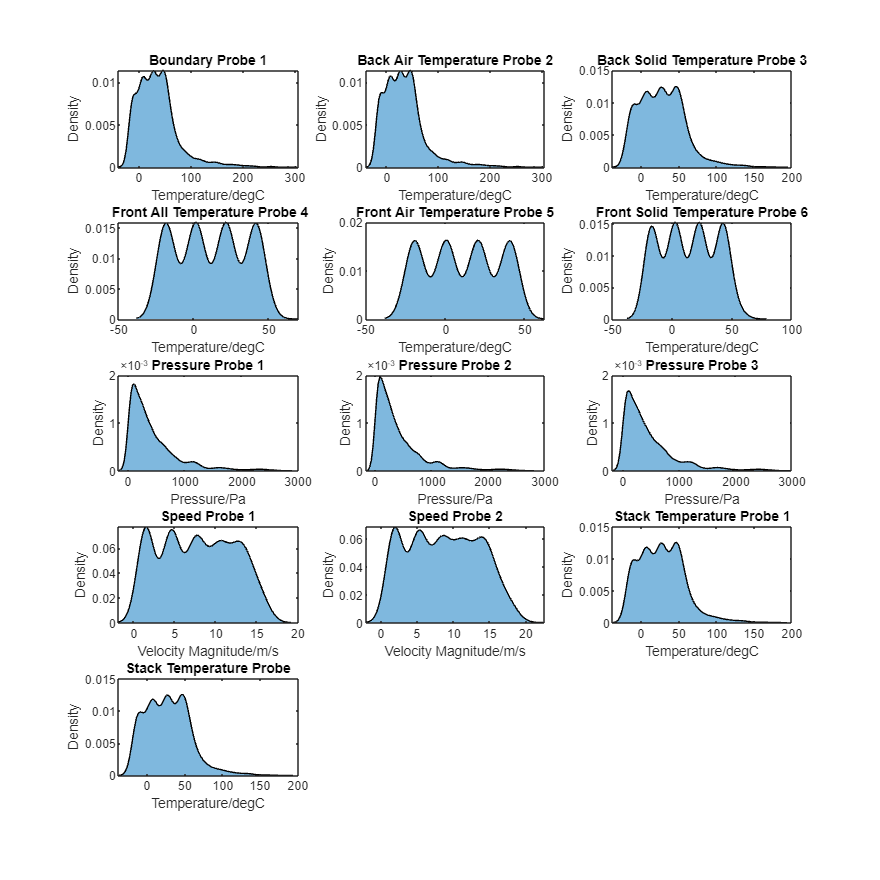

figure;
set(gcf,'Position',[0 0 1500 1500])
for i = targets
    index = find(targets==i);
    subplot(5,3,index);
    [f,xf] = kde(data{:,i});
    ar = area(xf,f);
    ar.FaceAlpha = 0.5;
    title(t_title(index))
    xlabel(t_label(index) + "/" + t_units(index))
    ylabel('Density')
end

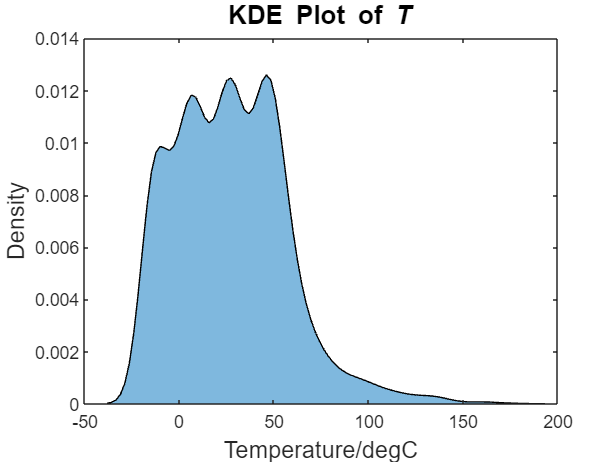

figure;
var = targets(12);
[f,xf] = kde(data{:,var});
ar = area(xf,f);
ar.FaceAlpha = 0.5;
index = targets==var;
set(gca, 'FontSize', 12)
title("KDE Plot of {\itT}", "FontSize",18)
xlabel("Temperature/" + t_units(index), "FontSize",16)
ylabel('Density', "FontSize",16)

## Histogram with Kernel Distribution Fit

### Individual Plot

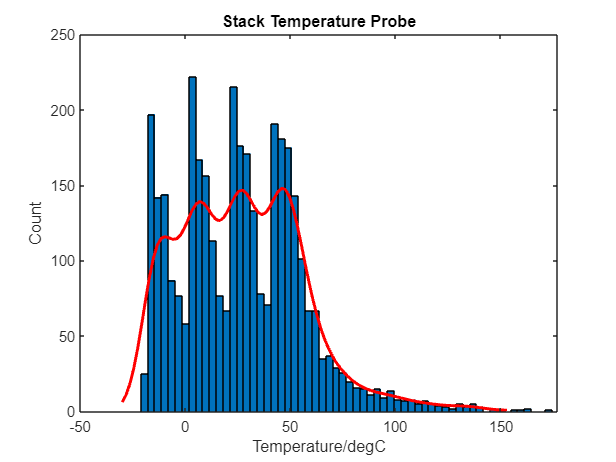

figure;
var = targets(13);
index = targets==var;
histfit(data{:, var}, [], 'kernel')
title(t_title(index))
xlabel(t_label(index) + "/" + t_units(index))
ylabel('Count')

### All Plots

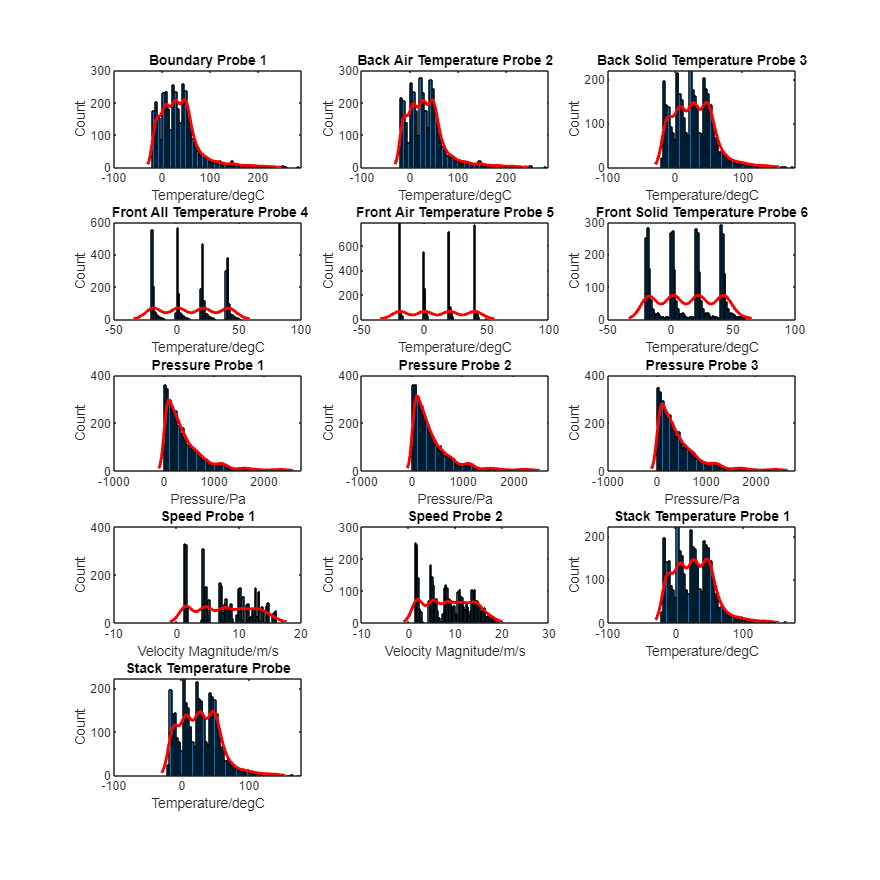

figure;
set(gcf,'Position',[0 0 1500 1500])
for i = targets
    index = find(targets==i);
    subplot(5,3,index);    
    histfit(data{:, i}, [], 'kernel')
    title(t_title(index))
    xlabel(t_label(index) + "/" + t_units(index))
    ylabel('Count')
end

## Check for Outliers

outlier = sum(isoutlier(data,"quartiles"))

outlier =      0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000   147.0000e+000   149.0000e+000    49.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000   201.0000e+000   210.0000e+000   193.0000e+000     0.0000e+000     0.0000e+000    48.0000e+000    48.0000e+000


## Check for Missing Data

missingval = sum(ismissing(data))

missingval =      0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000


## Stacked Plot

### Features

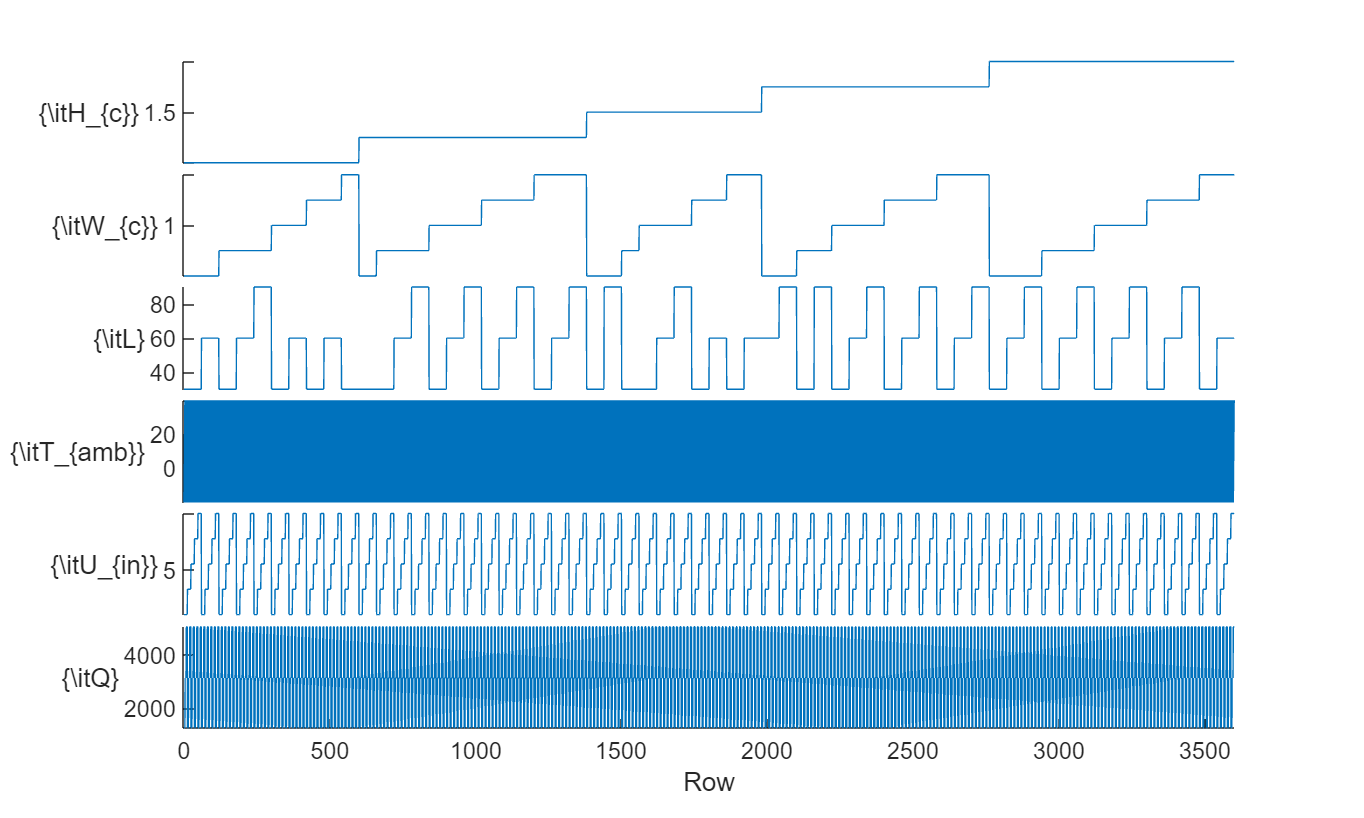

% Note: features looks like steps likely due to paramatric sweep
figure;
set(gcf,'Position',[0 0 1500 900])
lowerlim =0;
upperlim =3600;
s = stackedplot(data(:, features), 'FontSize',16', 'DisplayLabels',f_title);
xlim([lowerlim upperlim])

### Temperature Targets

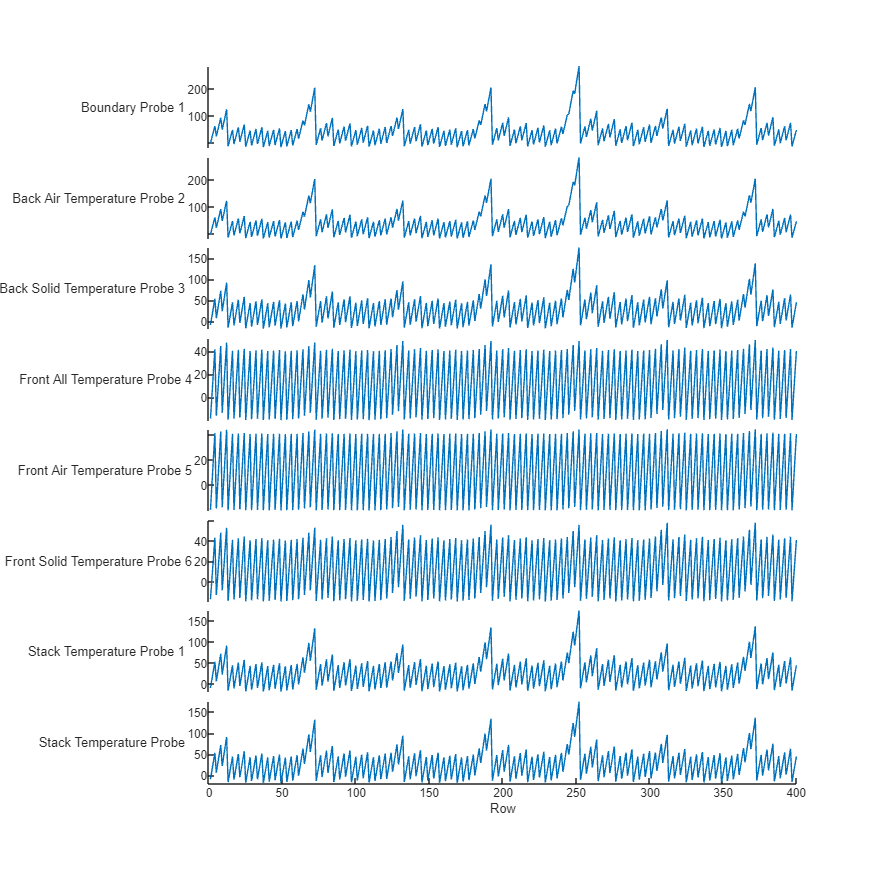

figure;
set(gcf,'Position',[0 0 900 900])
lowerlim =0;
upperlim =400;
sp = stackedplot(data(:, targets([1:6 12:13])));
set(sp, 'DisplayLabels',t_title([1:6 12:13]))
xlim([lowerlim upperlim])

### Pressure Targets

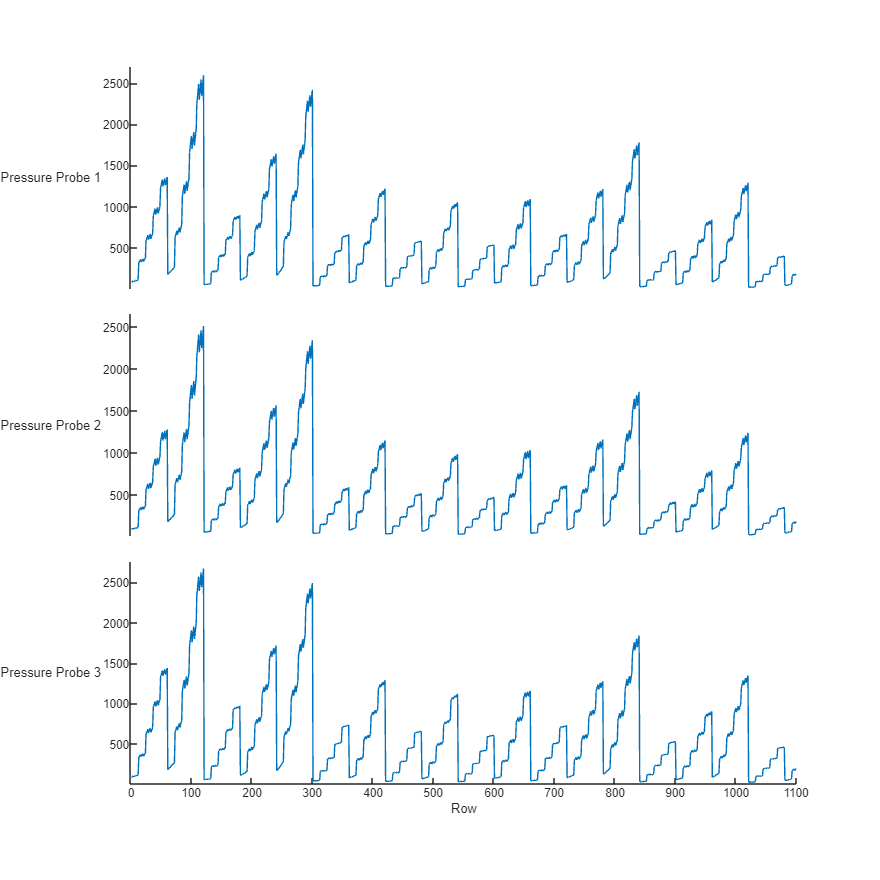

figure;
set(gcf,'Position',[0 0 900 900])
lowerlim =0;
upperlim =1100;
sp = stackedplot(data(:, targets(7:9)));
set(sp, 'DisplayLabels',t_title(7:9))
xlim([lowerlim upperlim])

### Velocity Targets

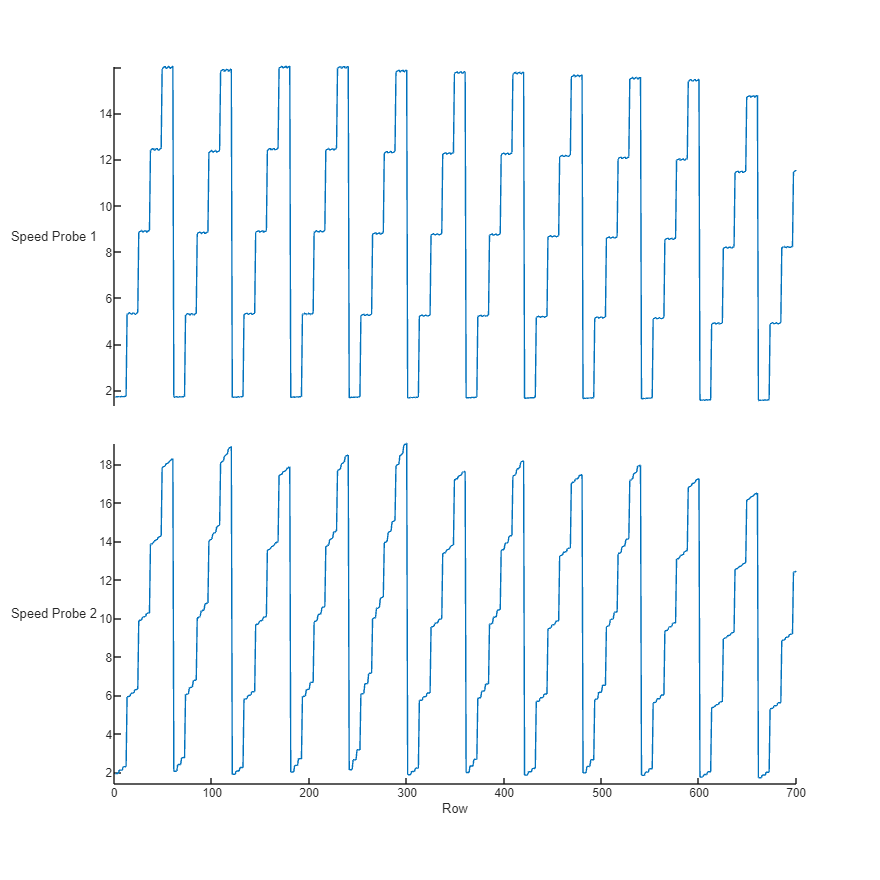

figure;
set(gcf,'Position',[0 0 900 900])
lowerlim =0;
upperlim =700;
sp = stackedplot(data(:, targets(10:11)));
set(sp, 'DisplayLabels',t_title(10:11))
xlim([lowerlim upperlim])

### Features With One Target

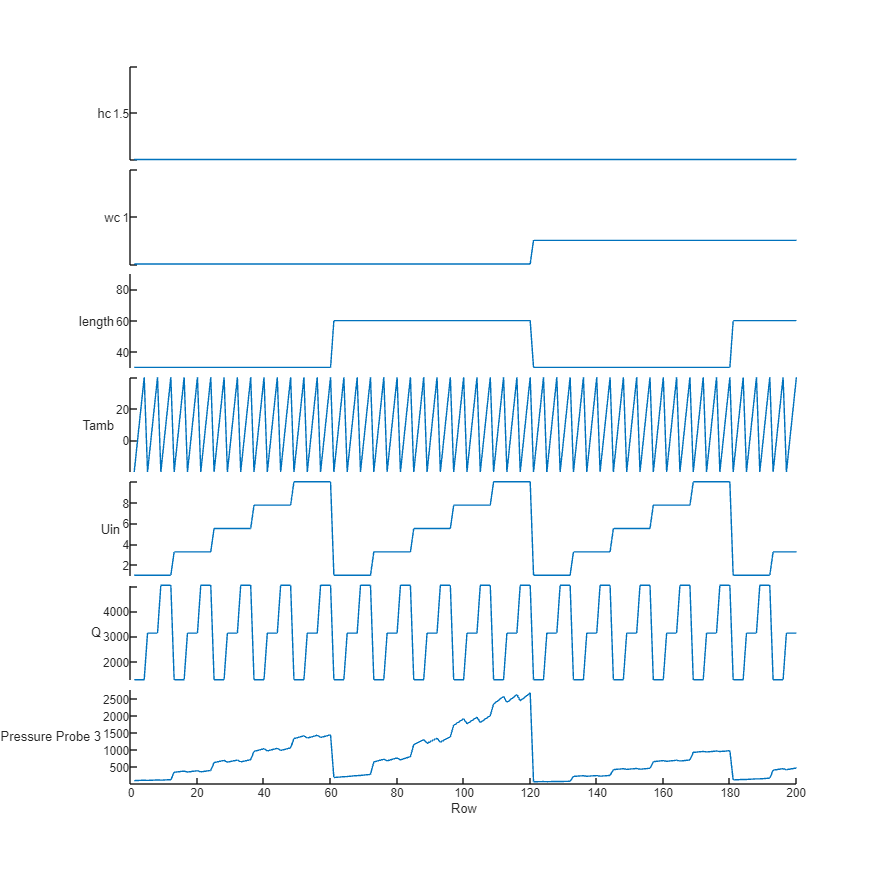

figure;
set(gcf,'Position',[0 0 900 900])
lowerlim =0;
upperlim =200;
var = targets(9);
sp = stackedplot([data(:, features()) data(:, var)]);
set(sp, 'DisplayLabels',[features() t_title(:, targets==var)])
xlim([lowerlim upperlim])

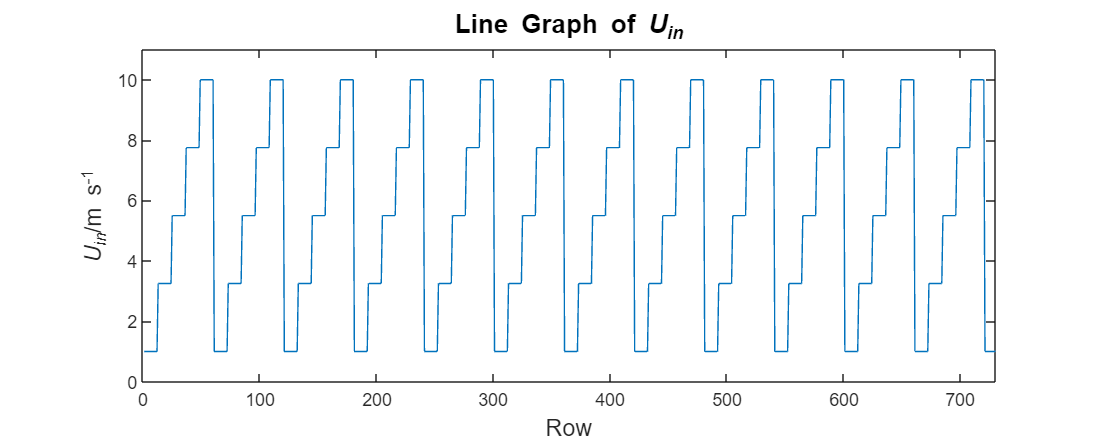

% Note: features looks like steps likely due to paramatric sweep
figure;
set(gcf,'Position',[0 0 1000 400])
plot(data, "Uin");
set(gca, 'FontSize', 12)
title("Line Graph of {\itU_{in}}", "FontSize",18)
ylabel("{\itU_{in}}/m s^{-1}", "FontSize",16)
xlabel("Row", "FontSize",16)
yticks(0:2:10)
ylim([0 11])
xlim([0 730])

## Boxplot

### Individual Plot

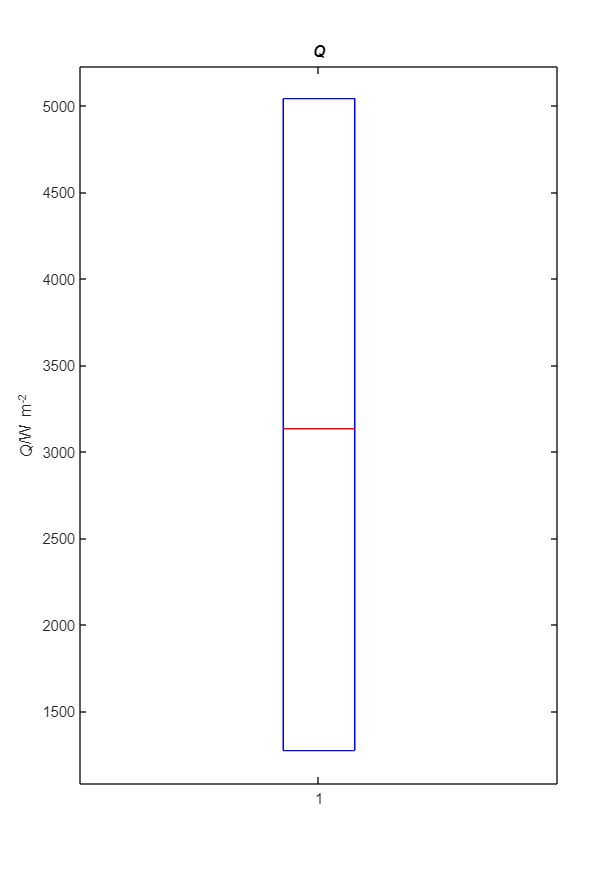

figure;
set(gcf,'Position',[0 0 700 1000])
var = "Q";
boxplot(data{:,var});
if(find(targets==var))
    index = targets==var;
    title(t_title(index))
    ylabel(t_label(index) + "/" + units(index))
else
    index = features==var;
    title(f_title(index))
    ylabel(f_title(index) + "/" + units(index))
end

### All Plots

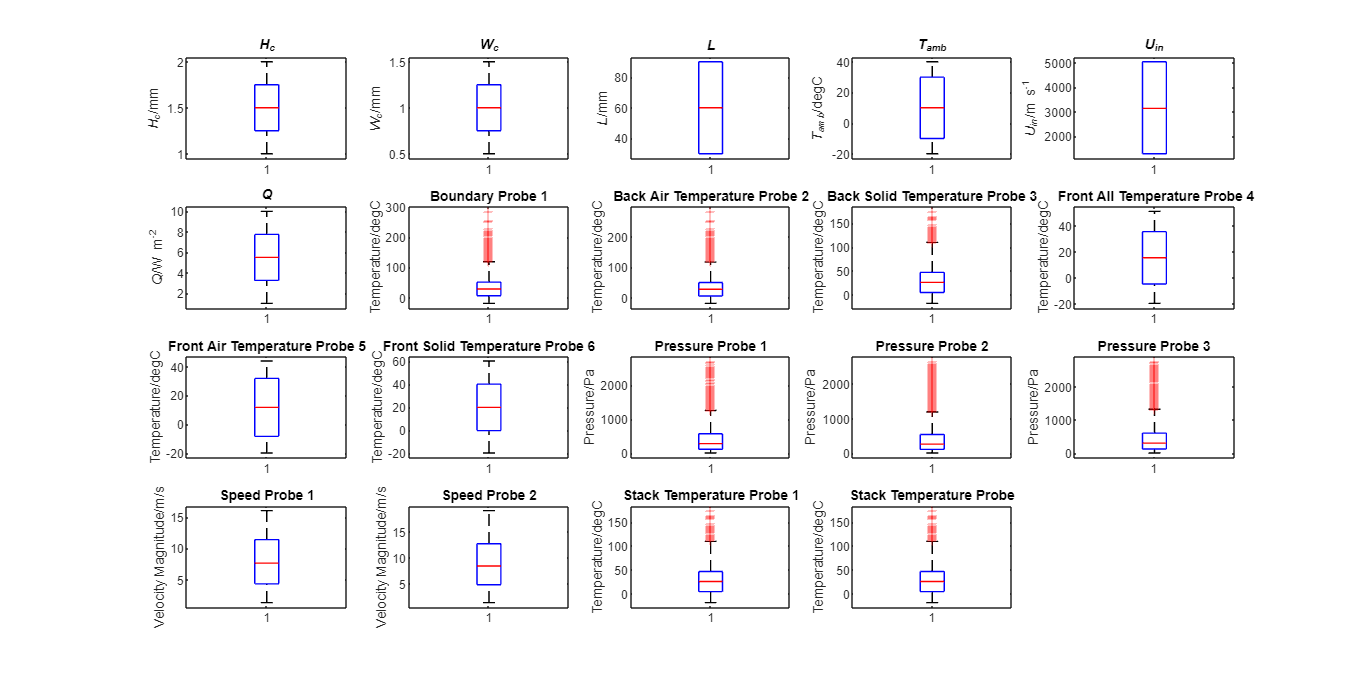

figure;
set(gcf,'Position',[0 0 2000 1000])
for i = 1:19
    subplot(4,5,i);
    boxplot(data{:,i});
    if(i>6)
        title(t_title(i-6))
        ylabel(t_label(i-6) + "/" + units(i))
    else
        title(f_title(i))
        ylabel(f_title(i) + "/" + units(i))
    end
end

## Histogram

### Indivdual Plot

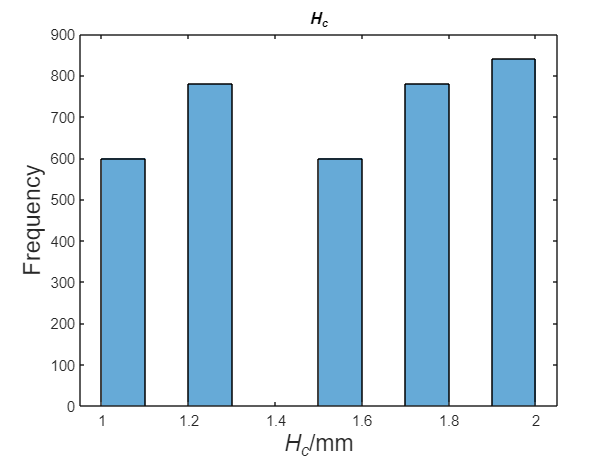

figure;
var = "hc";
histogram(data{:, var});
% title(var)
% xlabel(var + "/" + units(var))
% ylabel('Count')
if(find(targets==var))
    index = targets==var;
    title(t_title(index))
    xlabel(t_label(index) + "/" + units(index))
    ylabel("Frequency")
else
    index = features==var;
    xlabel(f_title(index) + "/" + units(index), 'FontSize',16)
    title(f_title(index))
    ylabel("Frequency", 'FontSize',16)
end

### All Plots

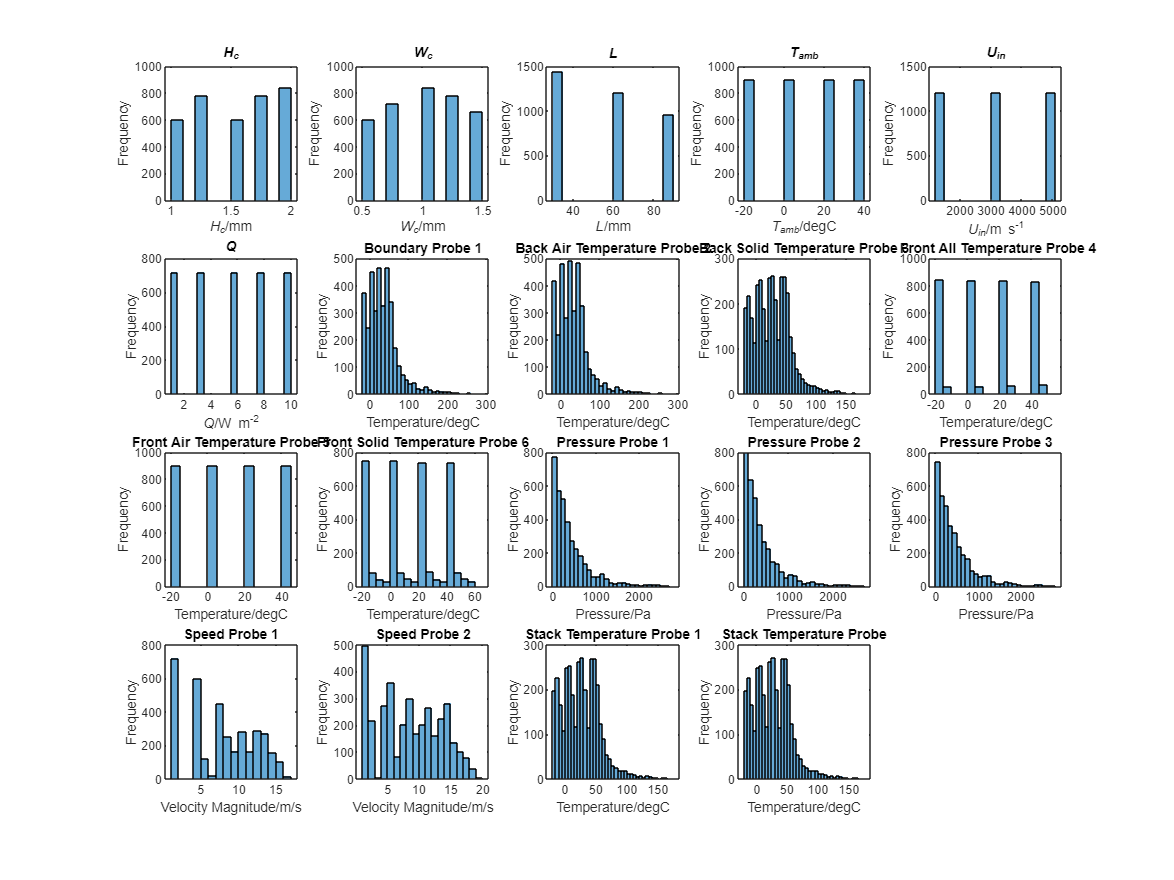

figure;
set(gcf,'Position',[0 0 2000 1500])
for i = 1:19
    subplot(4,5,i);
     histogram(data{:,i});
    if(i>6)
        title(t_title(i-6))
        xlabel(t_label(i-6) + "/" + units(i))
        ylabel('Frequency')
    else
        title(f_title(i))
        xlabel(f_title(i) + "/" + units(i))
        ylabel('Frequency')
    end
end

## CORRELATION HEATMAP

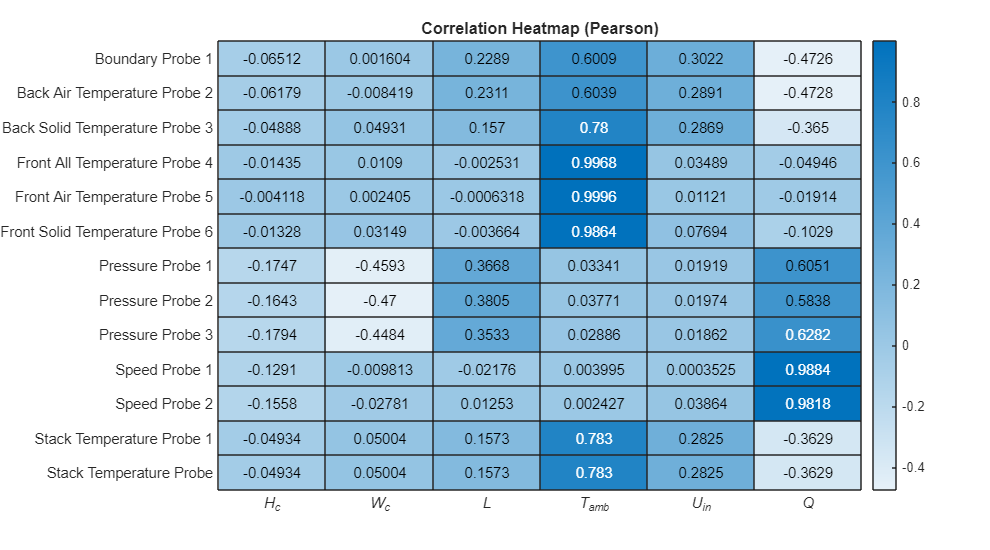

figure;
set(gcf,'Position',[0 0 900 500])
r = corr(data{:,:}, Type="Pearson");
r = r(7:19, 1:6);
% isupper = logical(triu(ones(size(r)),1));
% r(isupper) = NaN;
h = heatmap(r,'MissingDataColor','w');
title("Correlation Heatmap (Pearson)")
h.XDisplayLabels = f_title;
h.YDisplayLabels = t_title;

## CORRELATION MATRIX

figure;
set(gcf,'Position',[0 0 1500 1500])
[R,PValue] = corrplot(data(:,[1:6 15 19]),Type="Pearson")

R = 8×8 table
                                                hc             wc           length         Tamb            Q             Uin        PressurePaPressureProbe3    TemperaturedegCStackTemperatureProbe
                                            ___________    ___________    __________    __________    ___________    ___________    ________________________    ____________________________________

    hc                                                1      0.0052295       0.13213    1.2792e-17    -3.5937e-17              0            -0.17937                         -0.049338              
    wc                                        0.0052295              1     -0.070661    

PValue = 8×8 table
                                                hc            wc           length        Tamb          Q             Uin        PressurePaPressureProbe3    TemperaturedegCStackTemperatureProbe
                                            __________    ___________    __________    ________    __________    ___________    ________________________    ____________________________________

    hc                                               1        0.75377    1.7176e-15           1             1              1           2.0696e-27                         0.0030656             
    wc                                         0.75377              1    2.2004e-05           1

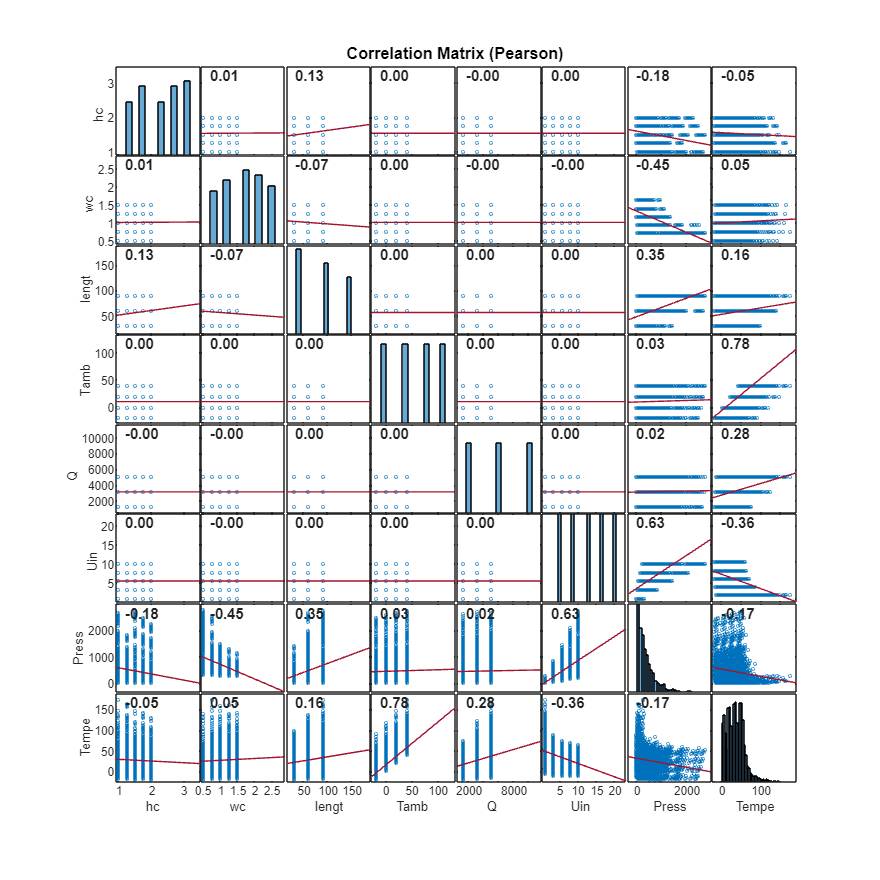

title('Correlation Matrix (Pearson)');

## Scatter by Group

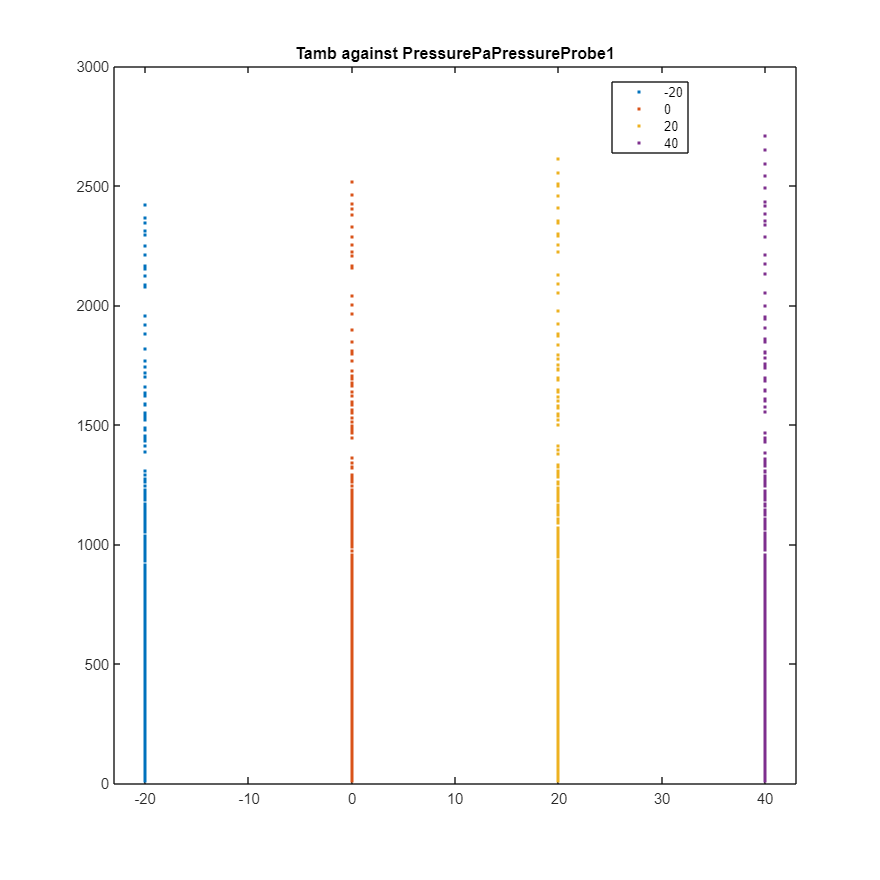

feature = features(4);
target = targets(7);
gscatter(data{:, feature},data{:, target},data{:, feature})
title(feature + " against " + target)

% xlabel(feature + "/" + units(feature))
% index = find(targets==target);
% ylabel(t_label(index) + "/" + units(index+6))

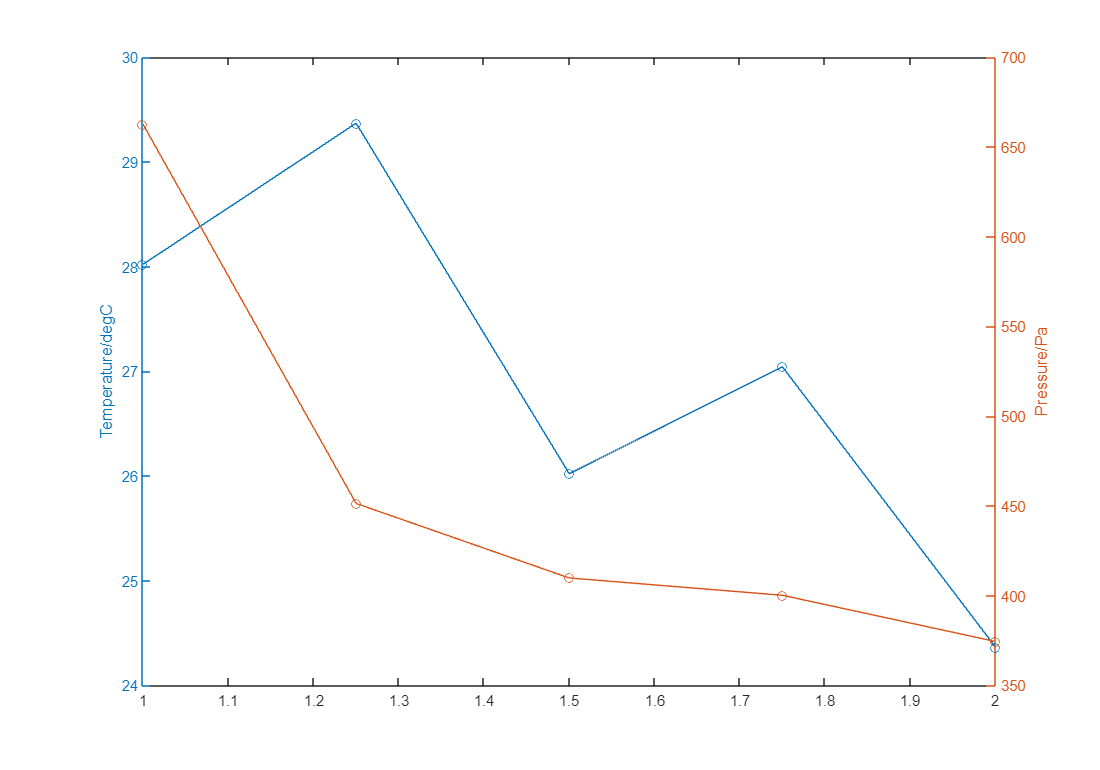

var = features(1);
figure
x = unique(data(:,var));

set(gcf,'Position',[0 0 1000 700])
yyaxis left
% boxchart(data{:,var}, data{:,"TemperaturedegCStackTemperatureProbe1"})
% hold on
mean = groupsummary(data{:,"TemperaturedegCStackTemperatureProbe1"},data{:,var},'mean');

plot(x{:,:}, mean, '-o')
ylabel("Temperature/degC")
hold off
% legend(["Weight Data","Weight Mean"])

yyaxis right
% boxchart(data{:,var}, data{:,"PressurePaPressureProbe3"}, "BoxWidth",0.1)
hold on
mean = groupsummary(data{:,"PressurePaPressureProbe3"},data{:,var},'mean');
plot(x{:,:}, mean, '-o')
ylabel("Pressure/Pa")
hold off

% legend(["Temperauture Mean","Pressure Mean"])
% xlabel(var)